## 计算实习题1

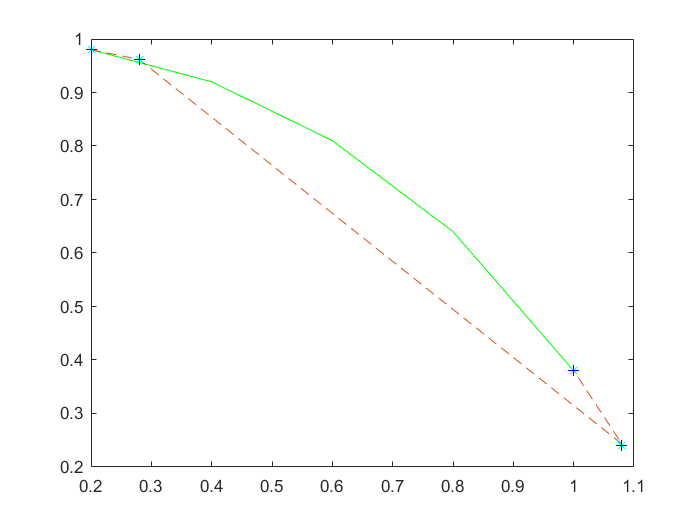

x1=[0.2,0.4,0.6,0.8,1.0];
y1=[0.98,0.92,0.81,0.64,0.38];
i=[0,1,11,10];
x2=0.2+0.08.*i;
y2_1=interp1(x1,y1,x2,'spline');    % 三次样条插值
[~,y2_2]=newton(x1,y1,x2);  % 牛顿插值
y2_3=lagr1(x1,y1,x2);   % 拉格朗日插值
plot(x1,y1,'g',x2,y2_1,'--',x2,y2_2,'c*',x2,y2_3,'b+');  % 绘图

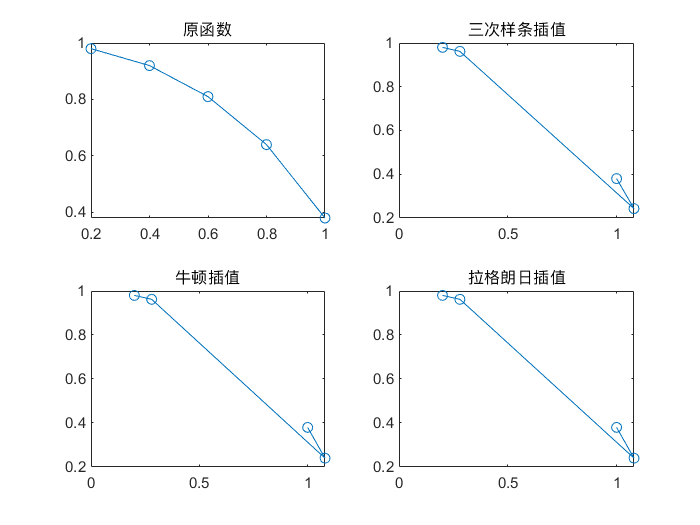

% 图像对比
subplot(2,2,1);
plot(x1,y1,'-o');
title('原函数')
subplot(2,2,2);
plot(x2,y2_1,'-o');
title('三次样条插值')
subplot(2,2,3);
plot(x2,y2_2,'-o');
title('牛顿插值')
subplot(2,2,4);
plot(x2,y2_3,'-o');
title('拉格朗日插值')

练习

% n=11;  m=61;
% x= -5:10/(m-1):5;
% y=1./(1+x.^2);
% z=0*x;
% x0=-5:10/(n-1):5;
% y0=1./(1+x0.^2);
% y1=lagr1(x0, y0, x);
% plot(x, z, 'r', x, y, 'k:',x, y1, 'r')
% gtext('Lagr.'), gtext('y=1/(1+x^2)')
% title('Lagrange')

## 相关函数

function [A,y]=newton(X,Y,x)
% 牛顿插值函数
% 输入参数：
%   X-样本点
%   Y-样本值
%   x-查询点
% 输出参数：
%   A-均差表
%   y-插值
n=length(X);    
m=length(x);
% 计算样本点的均差表A
A=zeros(n,n);A(:,1)=Y';
for j=2:n  % 求j阶均差
        for i=j:n  
            A(i,j)=(A(i,j-1)-A(i-1,j-1))/(X(i)-X(i-j+1));
        end
end
% 计算查询点x的插值
y=zeros(1,m);
for t=1:m  
    s=0.0;  z=x(t);
    for k=1:n  % 计算(x-xj)的累乘
        p=1.0;
        for j=1:k-1
            p=p*(z-X(j)); 
        end
        s=s+A(k,k)*p; % 含k阶均差的乘积项
    end
    y(t)=s;  % y为查询点的插值
end
end

function [A,y]=newton2(X,Y,x)
% 牛顿插值函数
% 参数含义
%   X-样本点
%   Y-样本值
%   x-查询点
n=length(X);m=length(x);
for t=1:m
    z=x(t); A=zeros(n,n);A(:,1)=Y';
    s=0.0;y=0.0;c1=1.0;
    for j=2:n
        for i=j:n
            A(i,j)=(A(i,j-1)-A(i-1,j-1))/(X(i)-X(i-j+1));
        end
    end
    C=A(n,n);
    for k=1:n
        p=1.0;
        for j=1:k-1
            p=p*(z-X(j));
        end
        s=s+A(k,k)*p;
    end
    ss(t)=s;
end
y=ss;
A=[X',A];
end


%newton1.m
%求牛顿插值多项式、差商、插值及其误差估计的MATLAB主程序
%输入的量:X是n+1个节点(x_i,y_i)(i = 1,2, ... , n+1)横坐标向量，Y是纵坐标向量，
%x是以向量形式输入的m个插值点，M在[a,b]上满足｜f~(n+1)(x)｜≤M
%注：f~(n+1)(x)表示f(x)的n+1阶导数
%输出的量：向量y是向量x处的插值，误差限R，n次牛顿插值多项式L及其系数向量C，
%差商的矩阵A
function[y,R,A,C,L] = newton3(X,Y,x,M)
n = length(X);
m = length(x);
for t = 1 : m
    z = x(t);
    A = zeros(n,n);
    A(:,1) = Y';
    s = 0.0; p = 1.0; q1 = 1.0; c1 = 1.0;
        for j = 2 : n
            for i = j : n
                A(i,j) = (A(i,j-1) - A(i-1,j-1))/(X(i)-X(i-j+1));
            end
            q1 = abs(q1*(z-X(j-1)));
            c1 = c1 * j;
        end
        C = A(n, n); q1 = abs(q1*(z-X(n)));
        for k = (n-1):-1:1
            C = conv(C, poly(X(k)));
            d = length(C);
            C(d) = C(d) + A(k,k);%在最后一维，也就是常数项加上新的差商
        end
        y(t) = polyval(C,z);
        R(t) = M * q1 / c1;
end
L = poly2sym(C);
end

function y=lagr1(X,Y,x)
% 拉格朗日插值函数
% 输入参数：
%   x0-样本点
%   y0-样本值
%   x-查询点
% 输出参数：
%   y-插值
n=length(X);  
m=length(x);
for i=1:m
     z=x(i);
     s=0.0;
    for k=1:n
          p=1.0;
          for j=1:n
               if j~=k
                  p=p*(z-X(j))/(X(k)-X(j));
               end
          end
         s=p*Y(k)+s;
    end
    y(i)=s;
end
end